## Amplitude Demodulation using Coherent Carrier

% Clear workspace, close figures, and command window
clc;
clear all;
close all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

% Play the original audio
disp('Playing the original audio...'); % Add a message to the console

Playing the original audio...


sound(x, fs); % Play the audio
pause(length(x) / fs); % Pause to allow time for audio playback
disp('Audio playback completed.'); % Display a completion message

Audio playback completed.


% Split audio into left and right channels
l = x(:, 1); % Left audio
r = x(:, 2); % Right audio

demod = zeros(size(x)); % Initialize an array to store the demodulated output

% Calculate the range of frequencies for the given signal
L = fft(l);
f = (-length(L)/2:length(L)/2 - 1) * fs / length(L);

% Define the time vector
t = (0:length(x) - 1) / fs;

% Modulation indices for under, critically, and over modulation
mu = [0.5, 1, 2];

% Define the carrier frequency
fc = 1e6;

% Generate the carrier wave
c = 2 * cos(2 * pi * fc * t);
c = reshape(c, size(l)); % Reshape it to match the audio signals

% Design a low-pass Butterworth filter
f_cut = 10000; % Cutoff frequency in Hz
Order = 10; % Filter order

% Design the low-pass Butterworth filter using butter
[b, a] = butter(Order, f_cut / (fs / 2), 'low');

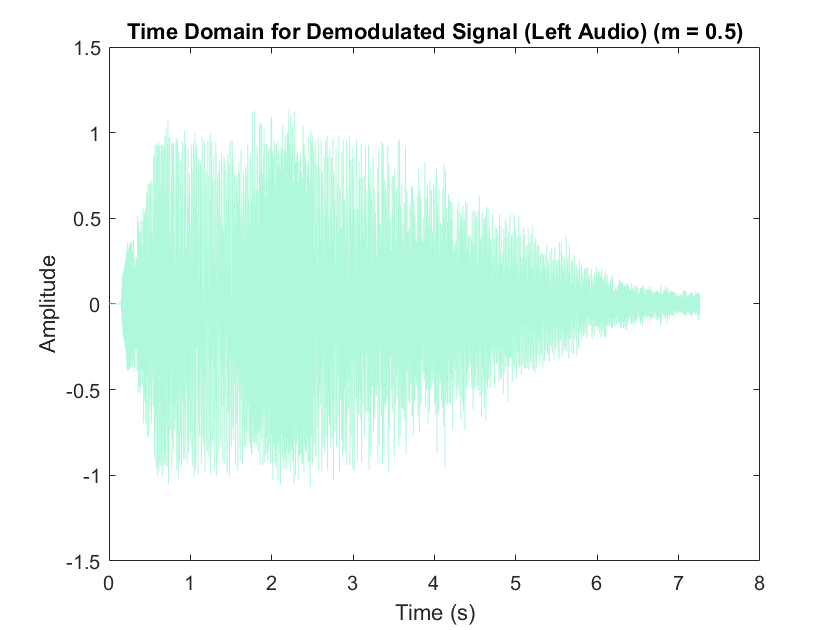

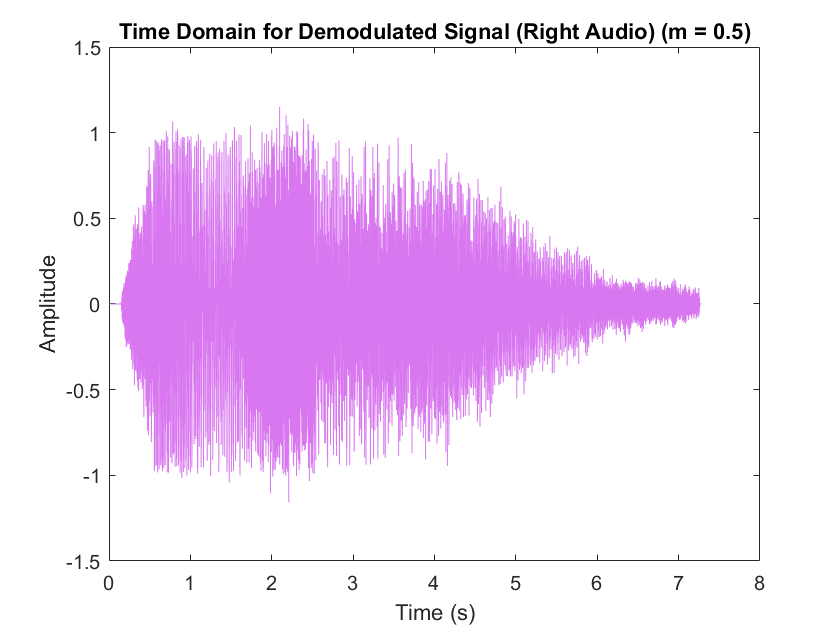

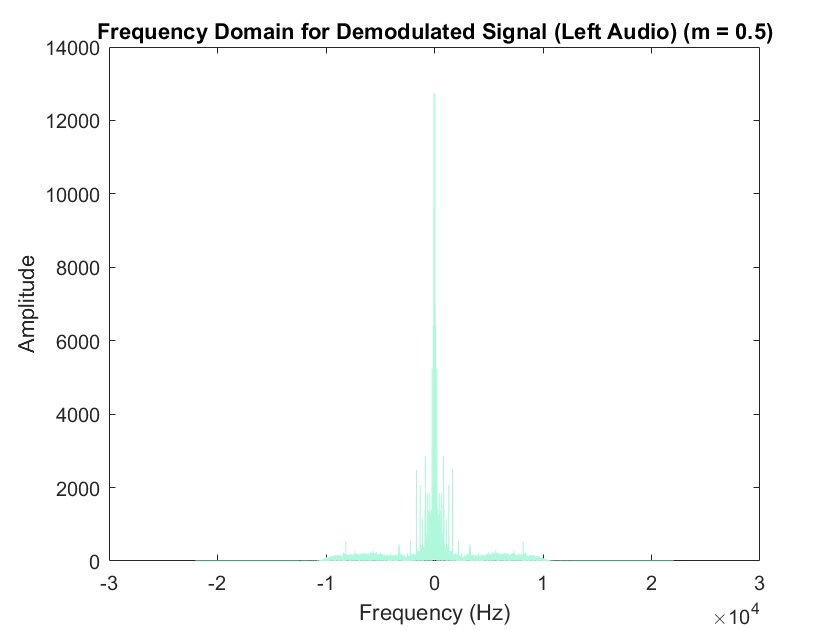

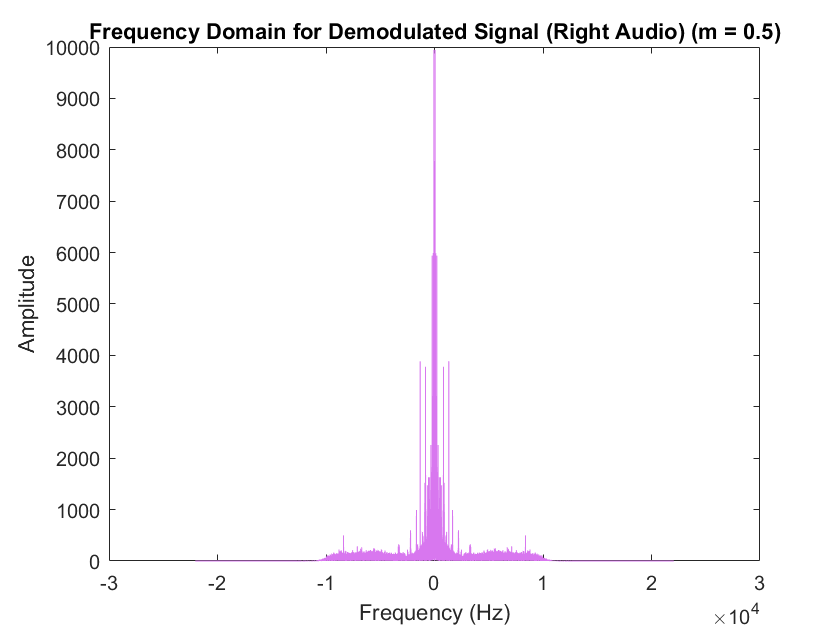

Playing demodulated audio (m = 0.5)


Audio Playback Completed.


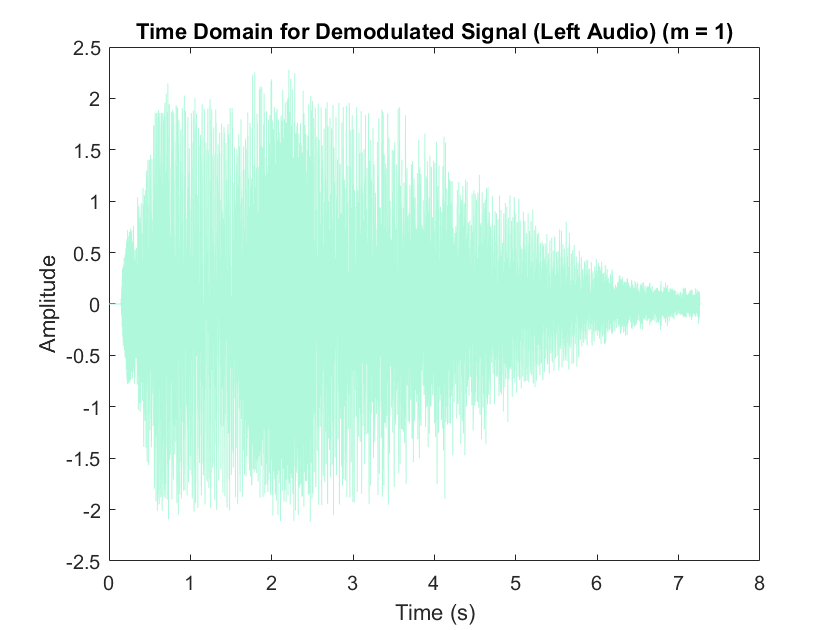

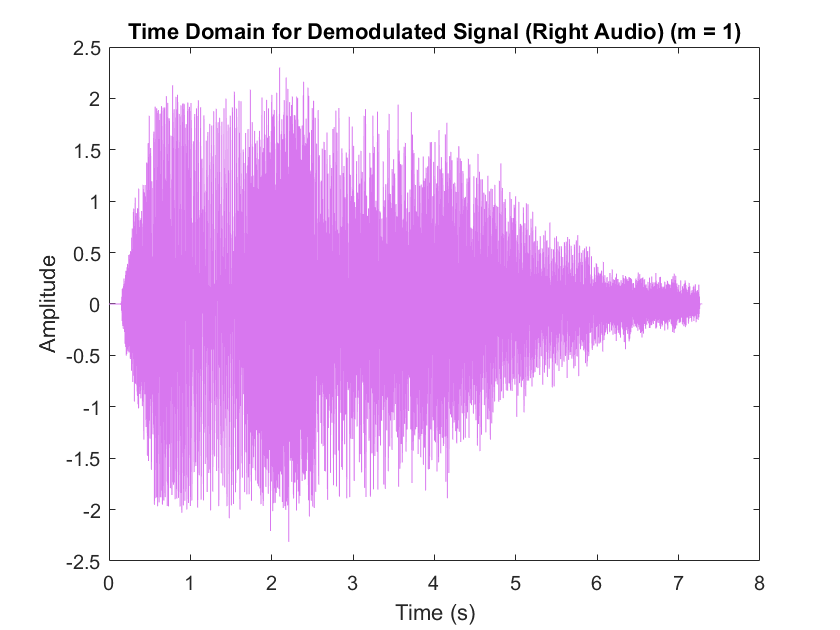

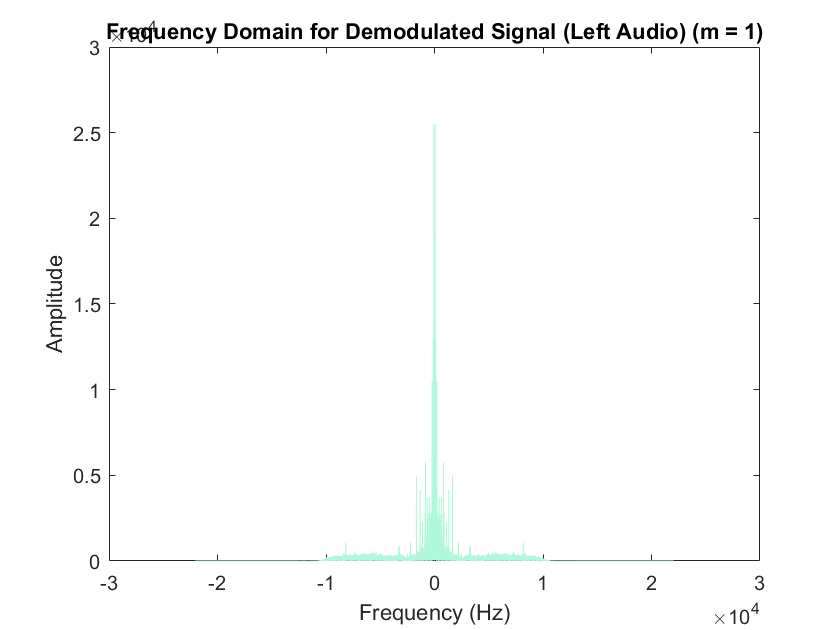

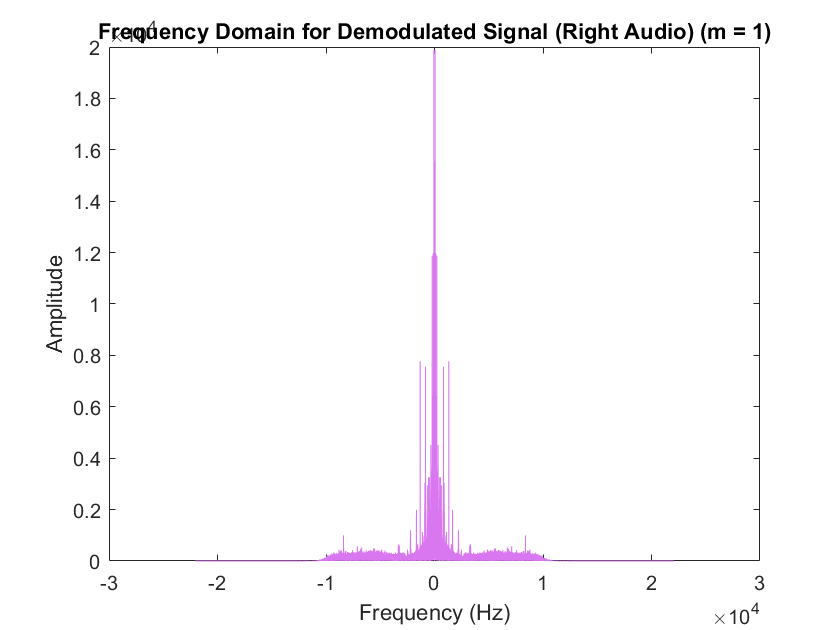

Playing demodulated audio (m = 1)


Audio Playback Completed.


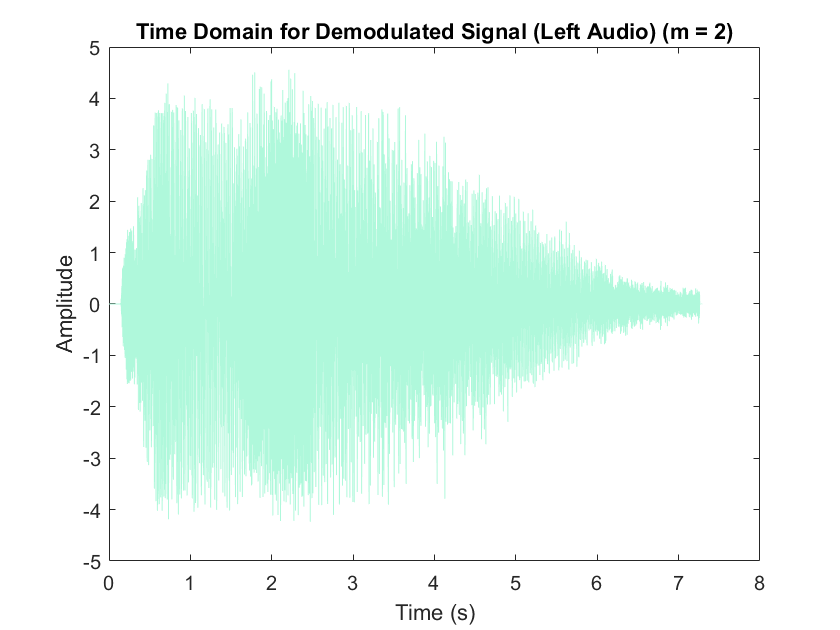

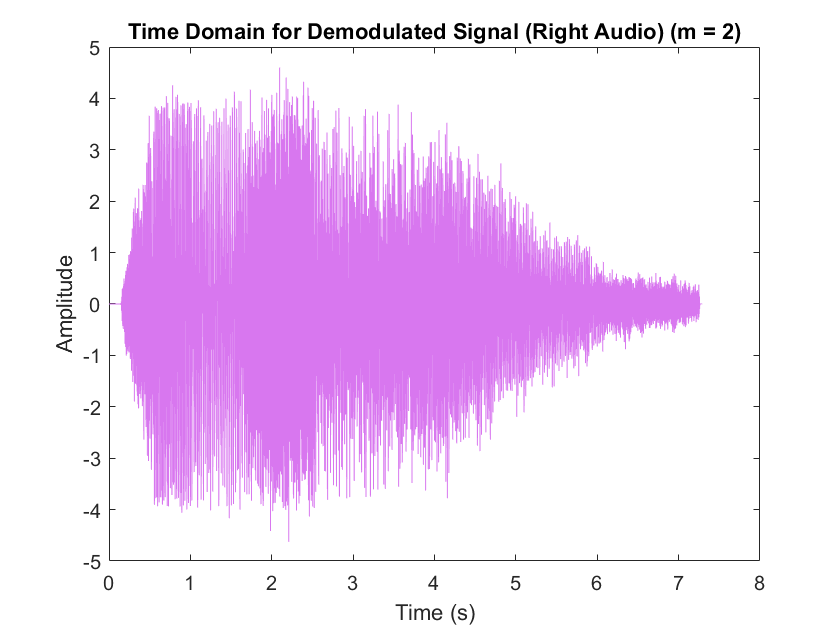

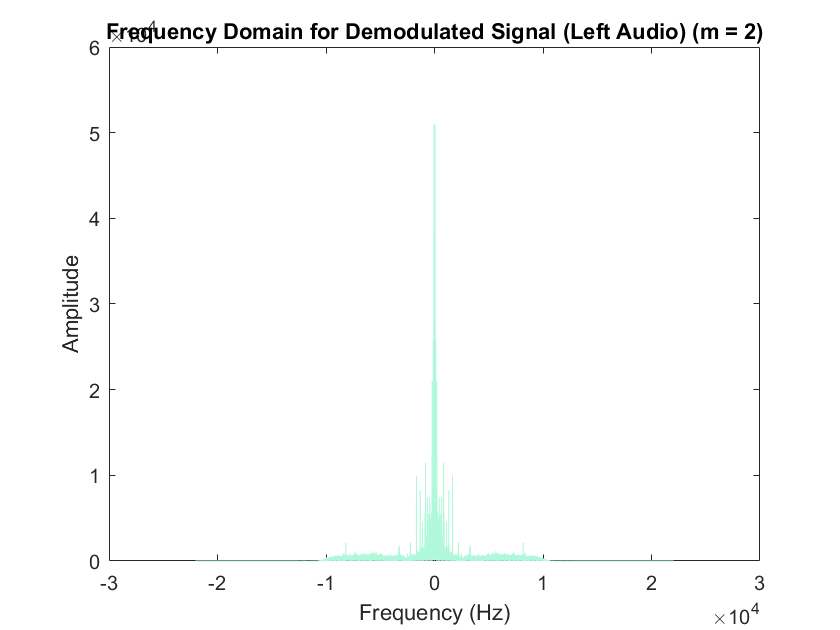

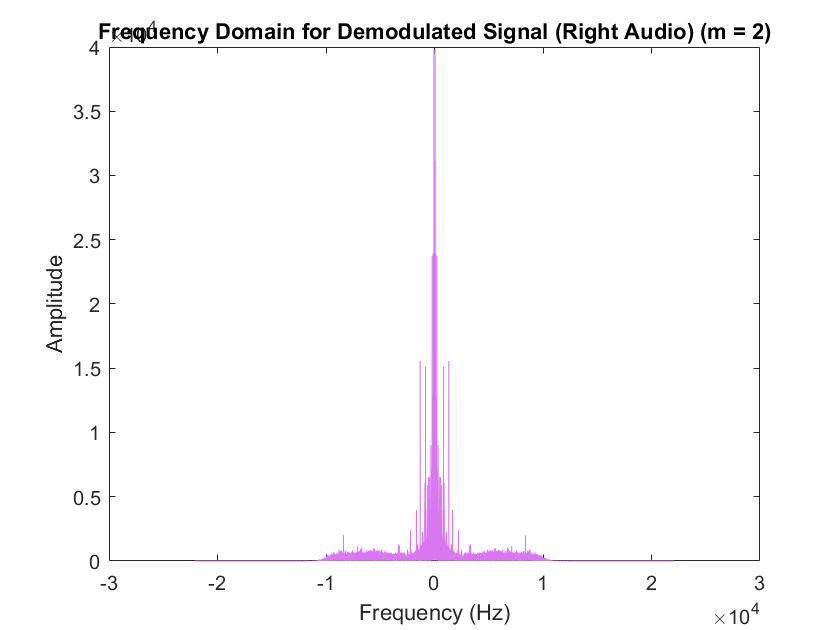

Playing demodulated audio (m = 2)


Audio Playback Completed.


% Performing coherent demodulation
for i = 1:length(mu)
    % Generate the modulated signal with element-wise multiplication
    m = mu(i); % Modulation index
    y_modulated_l = (m * l) .* c; % Use .* for element-wise multiplication
    y_modulated_r = (m * r) .* c;

    % Perform coherent demodulation
    y_demodulated_l = y_modulated_l .* c; % Carrier multiplication for demodulation
    y_demodulated_r = y_modulated_r .* c;

    % Apply the low-pass Butterworth filter to extract the message signal
    y_filtered_l = filtfilt(b, a, y_demodulated_l); % Use filtfilt for zero-phase filtering
    y_filtered_r = filtfilt(b, a, y_demodulated_r);
    
    % Combining the left and right audio signals
    demod(:, 1) = y_filtered_l;
    demod(:, 2) = y_filtered_r;
    
    % Plot the demodulated signal in the time domain (Left Audio)
    figure;
    plot(t, y_filtered_l, 'Color', '#aff8db');
    title(['Time Domain for Demodulated Signal (Left Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');

    % Plot the demodulated signal in the time domain (Right Audio)
    figure;
    plot(t, y_filtered_r, 'Color', '#d877ef');
    title(['Time Domain for Demodulated Signal (Right Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');

    % Compute the frequency domain for the demodulated signal (Left Audio)
    L = fft(y_filtered_l);
    
    % Plot the frequency domain for the demodulated signal (Left Audio)
    figure;
    plot(f, abs(fftshift(L)), 'Color', '#aff8db');
    title(['Frequency Domain for Demodulated Signal (Left Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');

    % Compute the frequency domain for the demodulated signal (Right Audio)
    R = fft(y_filtered_r);
    
    % Plot the frequency domain for the demodulated signal (Right Audio)
    figure;
    plot(f, abs(fftshift(R)), 'Color', '#d877ef');
    title(['Frequency Domain for Demodulated Signal (Right Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Play the demodulated and filtered audio
    disp(['Playing demodulated audio (m = ', num2str(m), ')']); % Add a message to the console
    sound(demod, fs); % Play the demodulated and filtered audio using the 'sound' function
    pause(length(demod) / fs); % Pause to allow time for audio playback
    disp('Audio Playback Completed.') % Display the completion message
end